clear;clc;close all;

Ra = 0.5; La = 0.01;
J = 1; B = 0;
Ke = 1.8; Kt = 1.8;
Va = 240; TL = 0;

dxdt = @(t,x)[(Va - Ra*x(1) - Ke*x(2)) / La;
    (Kt*x(1) - B*x(2) - TL) / J];

tspan = [0 2];
x0 = [0;0];
[t, x] = ode45(dxdt, tspan, x0);

ia = x(:,1);
omega = x(:,2);
Te = Kt*ia;

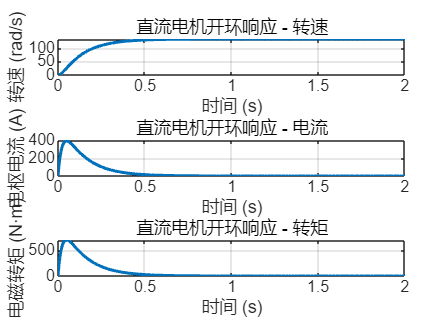

figure;
subplot(3,1,1);
plot(t, omega, 'LineWidth', 1.5);
grid on; xlabel('时间 (s)'); ylabel('转速 (rad/s)');
title('直流电机开环响应 - 转速')

subplot(3,1,2);
plot(t, ia, 'LineWidth', 1.5);
grid on; xlabel('时间 (s)'); ylabel('电枢电流 (A)');
title('直流电机开环响应 - 电流');

subplot(3,1,3);
plot(t, Te, 'LineWidth', 1.5);
grid on; xlabel('时间 (s)'); ylabel('电磁转矩 (N·m)');
title('直流电机开环响应 - 转矩')

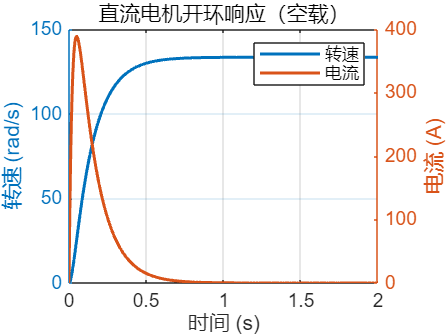

figure;
yyaxis left
plot(t, omega, 'LineWidth', 1.5);
ylabel('转速 (rad/s)');
yyaxis right
plot(t, ia, 'LineWidth', 1.5);
ylabel('电流 (A)');
grid on; xlabel('时间 (s)');
title('直流电机开环响应（空载）');
legend('转速', '电流');